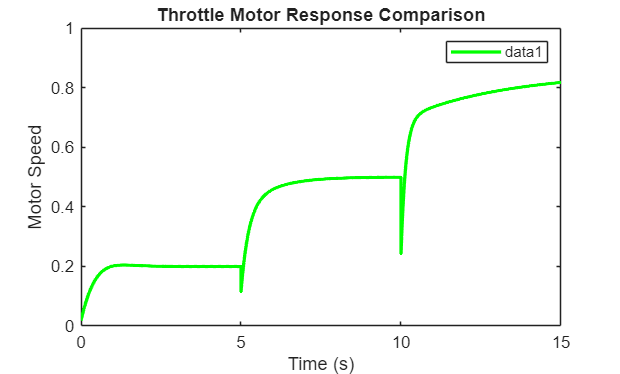

clc; clear; close all;

load('pid_data.mat');
load('gs_data.mat');

figure;
hold on; grid on;

step(G,'r--');
step(T_pid,'b');
plot(t_total,y_total,'g','LineWidth',2);

legend show

title('Throttle Motor Response Comparison');
xlabel('Time (s)');
ylabel('Motor Speed');

if ~exist('results','dir')
    mkdir('results');
end

saveas(gcf,'results/comparison_plot.png');